# Inverse Beam Former

clearvars

#### Work was performed in rearranging the HF simulation to handle element level simulation.

#### This will result in the ability to perform beam level simulation.

dataFileName = "C:\Users\pbergman\GIT25\ZDATA00\airTrackReturn_20220627_044140.mat";
load(dataFileName);

[lat1_, lon1_, ~, ~] = ROTH.ohsElementPositions();
alt1_ = lat1_.*0.0;

elementData = ROTH.inverseBeamForm( radarReturn_, ROP, az_, lat1_, lon1_, alt1_);
elementData = elementData + 0.01*randn(size(elementData)) + 0.01*randn(size(elementData))*1i;

elementDataFileName = ROTH.createDataFileName( 'elementData', ROP );

save( elementDataFileName, "ROP", "elementData","-v7.3");

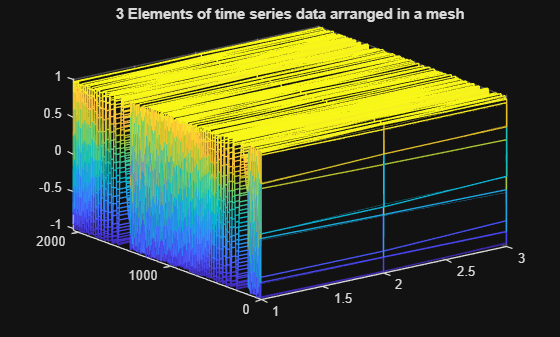

mesh(real(elementData(1:2048,1:3)))
title("3 Elements of time series data arranged in a mesh");